# SysMIC M1: Assignment 3

If you need help for this assignment please make use of the [session 3 forum](http://sysmic.ac.uk/moodle/mod/forum/view.php?id=4208).

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2367](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2367).

After submission you can access model answers via the [session 3 review](https://sysmic.ac.uk/moodle/mod/quiz/view.php?id=3198) activity.

`NAME: Jade Lau`

## Exercise 2.2.5

i) Use the command `rng(1)` to fix the starting seed for the random number generator, then use function `adj_matrix_sym` to create an undirected adjacency matrix with 100 nodes and randomly distributed edges.

*Note: Don't try to create a view of this matrix - for a network with large numbers of nodes/edges the algorithms MATLAB uses to contruct visualisations require significant processing time to compute.*

ii) Find the degree distribution of the matrix, and plot it using `histogram`.

Hint. As it is undirected we can find the degree distribution using *either* row or column sums.

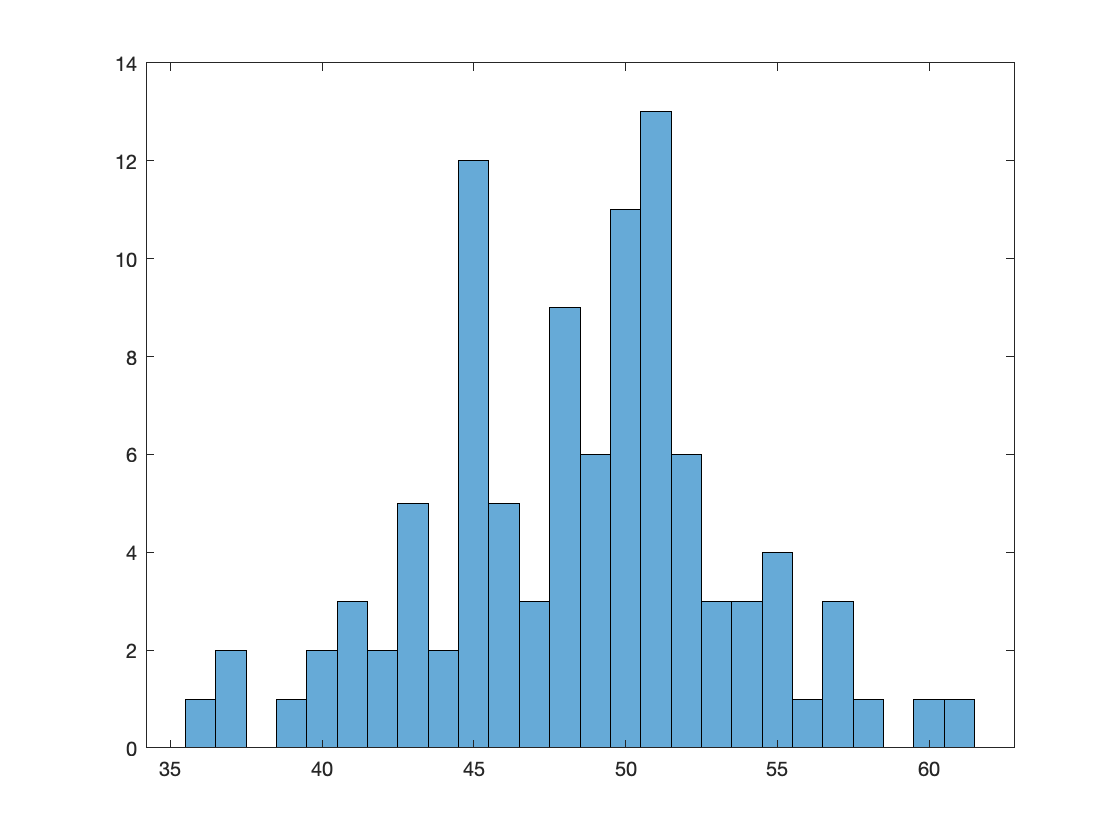

%answer
rng(1);
mat = adj_matrix_sym(100);
degree_in = sum(mat);
histogram(degree_in);

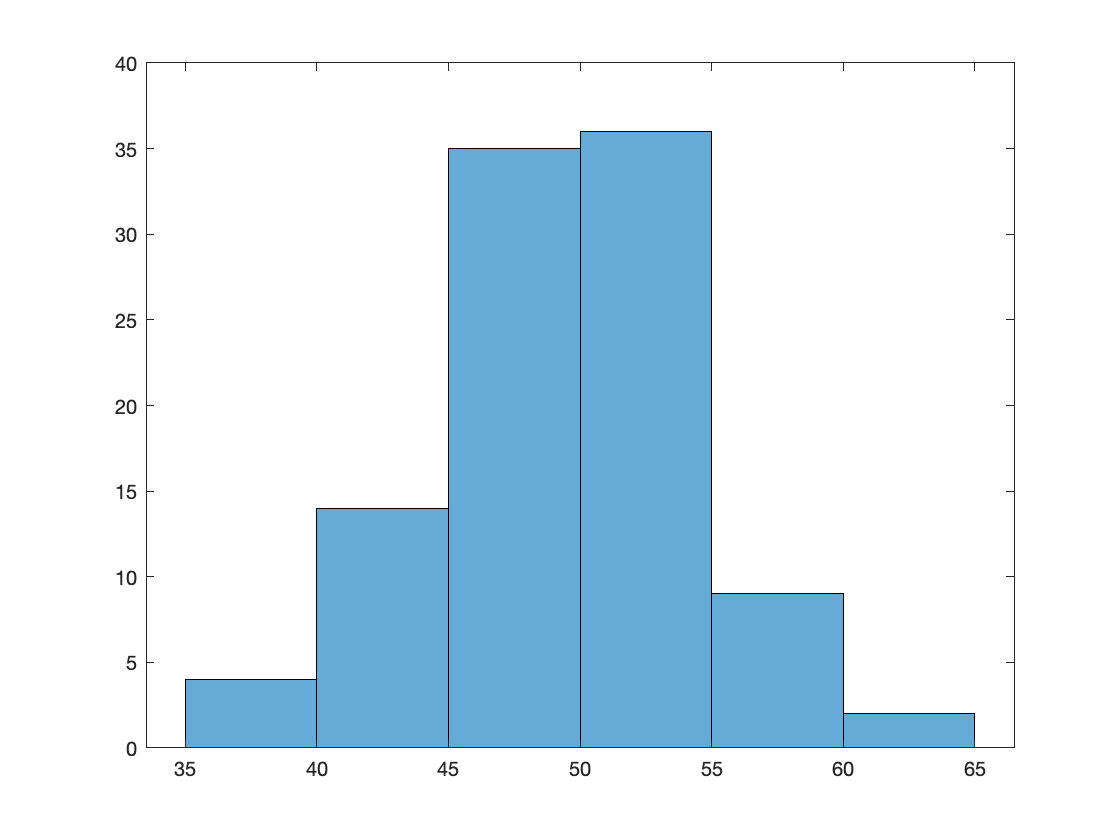

% we see a lot of "noise" in the bins
% to see better the underlying distribution
% we can set hostogram bin range to 35:5:65 
%  i.e. 35, 40, 45 ... 60, 65
histogram(degree_in,35:5:65)

iii) Calculate the average degree of the network.

%answer

%answer
total_edges = sum(degree_in);
av_degree = total_edges / 100;

avg_deg = mean(degree_in)

avg_deg = 48.4800

iv) Calculate the clustering coefficients and the average clustering coefficient using `avgClusteringCoefficient`.

%answer
[acc, c] = avgClusteringCoefficient(mat)

acc = 0.4882

c =     0.4996
    0.4827
    0.4819
    0.4824
    0.4936
    0.5153
    0.5069
    0.4623
    0.4970
    0.4789


v) Plot the clustering coefficient distribution using `histogram`. 

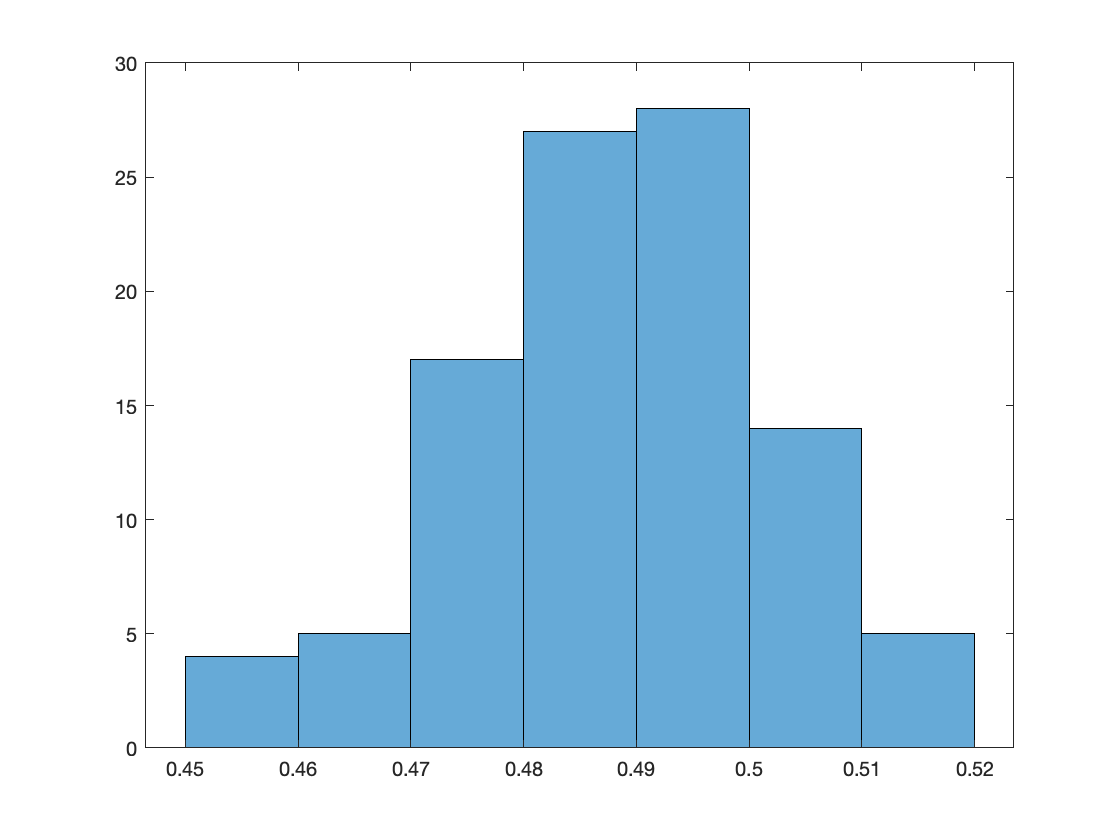

%answer
histogram(c)

% The function that generates the random networks sets each value in the adjacency matrix to 1 or 0 with 50% probability. This means we expect on average the neighbours to be half-maximally connected to each other and this is why the histogram of clustering coefficients lies close to the value 0.5.
% 
% This also explains the average degree being 50 each node will be connected to approximately half the other nodes in the network.


## Exercise 2.2.8

Download the network information for the pentose phosphate pathway (PPP) in **Homo sapiens**. 

Note. If you are using MATLAB 2019b due to a compatibility issue you will have to use the alternative file [R-HSA-71336_fixed.sbml](https://sysmic.ac.uk/textbook/R-HSA-71336_fixed.sbml) 

i) Import the model into MATLAB and examine the number of species and reactions

%answer

% Set warnings to hidden
warning ('off','all'); % Import the file
mm = sbmlimport('R-HSA-71336.sbml'); % Turn warnings back on
warning ('on','all');
mm

mm =    SimBiology Model - Pentose phosphate pathway 

   Model Components:
     Compartments:      1
     Events:            0
     Parameters:        0
     Reactions:         20
     Rules:             42
     Species:           42
     Observables:       0


The PPP network contains 42 species and 20 reactions.

ii) Extract the adjacency matrix for the network and node names. View the network using `imagesc` and check it is consistent with the expected structure.

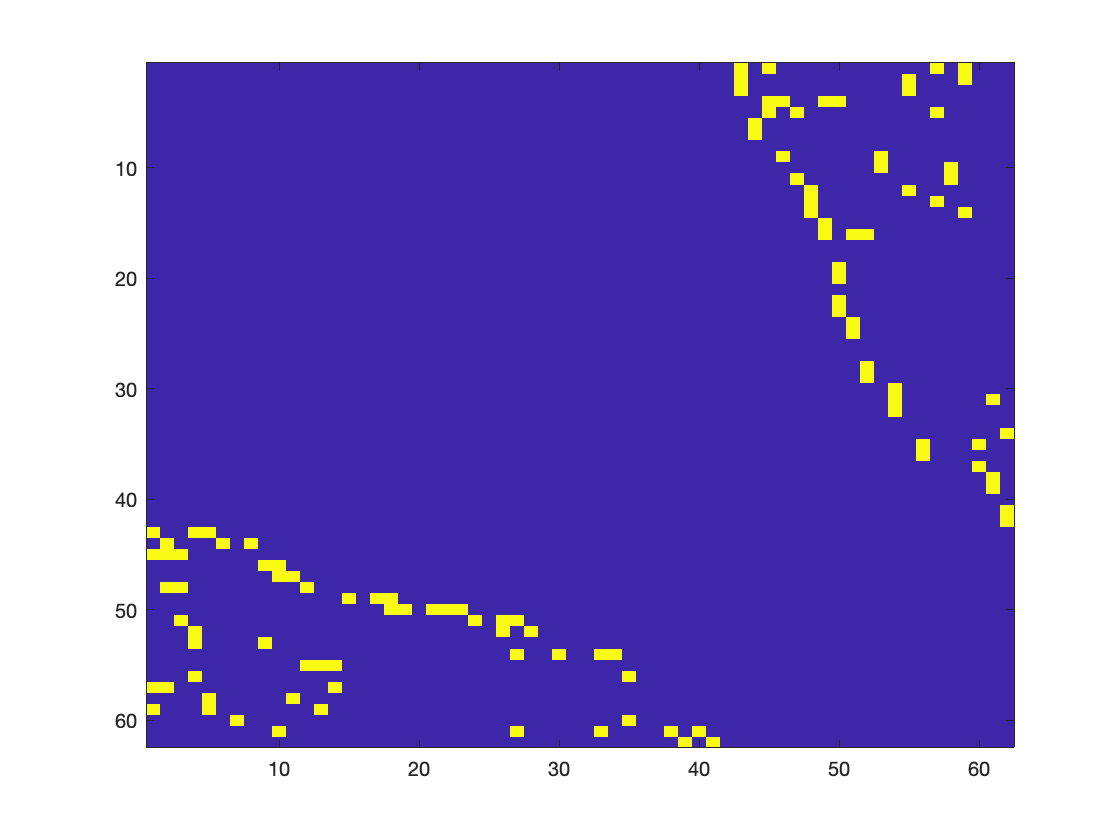

%answer

% Extract information about the network matrix
[mm_adj , Headings] = getadjacencymatrix(mm);

imagesc(mm_adj)

The matrix rows are species then reaction nodes, so rows 1-42 correspond to species and 43-62 correspond to reactants, and the connections between species-to-reaction (top-right portion) or reactions-to-species (bottom-left corner). 

iii) Use MATLAB to determine the number of nodes and edges in the PPP network.

%answer
% Check the number of nodes
no_nodes = size(mm_adj ,1)

no_nodes = 62

% Check the number of edges
no_edges = sum(sum(mm_adj))

no_edges =    (1,1)      114


iii) In glycolysis cytosolic G6P is converted to F6P. What happens to cytosolic G6P in the PPP network? 

Hint: check the Headings file for `'G6P'` in the `'cytosol'. `Then look up its connections in the adjacency matrix to which reaction it is connected to.

%answer
% loop over through nodes names
for i=1:length(Headings)
    species = 'G6P';
    location = 'cytosol';
% % display names containing both species AND location
    if contains(Headings(i), species) && contains(Headings(i), location)
        disp([num2str(i) Headings(i)]);
% %         if Headings(i) == 'G6P (cytosol)'
% %             disp([num2str(i) Headings(i)]);
% %         end
    end
end

    {'30'}    {'G6PD dimer and tetramer (cytosol)'}

    {'32'}    {'G6P (cytosol)'}



% 
% % loop over through nodes in matrix
for i=1:length(mm_adj)
 % display edges starting from node 51
     if mm_adj(32,i) == 1
     disp([num2str(i) Headings(i)]);
    end
end

    {'54'}    {'alpha-D-glucose 6-phosphate + NADP+ => D-glucono-1,5-lactone 6-phosphate + …'}

